# Getting started with the GUM toolbox

## What is GUM?

GUM is a versatile Matlab toolbox for standard and nonlinear regressions. The regression models that can be defined include standard Generalized Linear Models (GLMs), Generalized Additive Models (GAMs) and many more nonlinear regression models that belong to the larger category of Generalized Unrestricted Models (GUMs). The tutorial below is intented to show what these models are, how they can be fitted with the toolbox. We'll give you a glimpse of how the framework can help you make the most of your behavioral data, neural data - or just any type of data you might collect.

  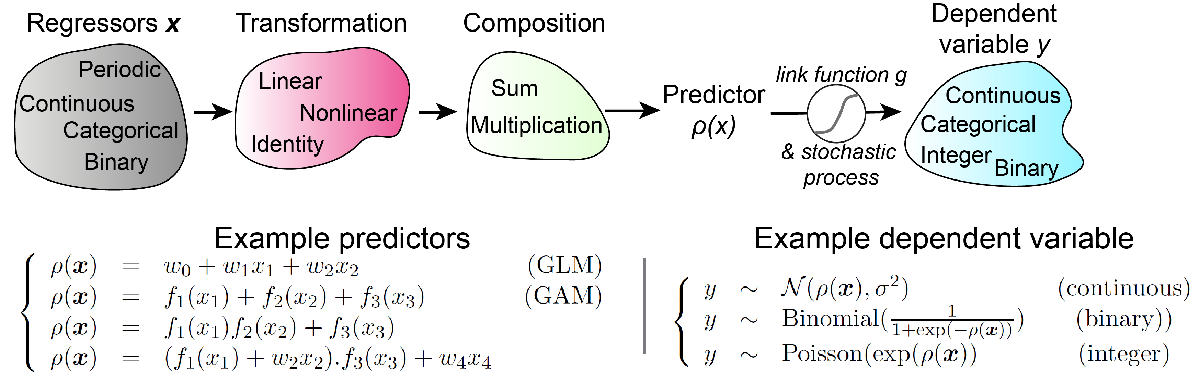

The toolbox uses object-oriented programmation and R-style formulas, which allow to conveniently define a model, fit it to data and plot/display the results (and tons of other options) in a handful of lines.

## Installation

- Download/clone the toolbox from [https://github.com/ahyafil/gum](https://github.com/ahyafil/gum).

- Add folder and subfolders to Matlab path: in the command line, write something like` addpath(genpath(FolderWhereYouPlacedThePackage));`

- Add the [Matrix Computation Toolbox](https://www.mathworks.com/matlabcentral/fileexchange/2360-the-matrix-computation-toolbox) to your Matlab path

- Enjoy!

## **A (not-so) short tutorial: **

This tutorial presents an overview of the key features of the GUM toolbox. Explore other tutorials for a more in-depth coverage of the toolbox.

In this tutorial we will use a dataset  where one monkey performed a motion discrimination task. In each trial, the animal is presented with a sequence of 7 motion stimuli (motion *pulses*), each with some degree of motion towards left or right. The animal had to report at the end of the sequence whether the overall motion was towards the left or right. We will use different regression models where the dependent variable is subject choice (a binary variable: 1 for rightwise and 0 for leftwise response), while the motion of individual pulses constitute the main independant variables. The paradigm is presented in more details in [Yates et al., Nature Neuroscience 2017](https://www.nature.com/articles/nn.4611).

The following function downloads the online dataset as a table and performs some minor pre-processing.

 T = load_online_dataset();

loading csv file from url...done


`Stimulus1` is the motion from the first stimulus pulse, `Stimulus2` is the motion of the stimulus pulse, and so on. Value is positive if this motion is towards the right (and so we expect it to bias the subject towards performing a rightward response), negative otherwise. 

head(T)

    resp    target    session     Stimulus     Stimulus1    Stimulus2    Stimulus3    Stimulus4    Stimulus5    Stimulus6    Stimulus7    accuracy     response    trial
    ____    ______    _______    __________    _________    _________    _________    _________    _________    _________    _________    _________    ________    _____

     0        0          1       1×7 double       -10           -9          -10           -7          -13          -12          -11       "correct"       -1         1  
     0        0 

### Simple GLM

For all models we follow the same three-step procedure:

- define the model

- estimate the weights (and possibly hyperparameters) of the model

- plot the weights, compare models or other post-hoc analyses of the fitted model

#### Defining a model

We can define a simple GLM by passing the table and a simple GLM formula as input to GUM (exactly as in *glmfit* of the Statistics toolbox). The type of observation (`'binary', 'normal', 'Poisson'` or `'neg-binomial`') can be passed as an extra argument but here we're using binary observations which is the default option.

M = gum(T,'resp ~ (Stimulus1 + Stimulus2 + Stimulus3 + Stimulus4 + Stimulus5 + Stimulus6 + Stimulus7)',...
    'prior','none');

We are working here in a frequentist setting, not a Bayesian setting, which we declare by removing the automatic prior set on weights: `gum(....,'prior','none'). `[The parenthesis in the formula is there to plot all weights into a single subplot. It does not affect the results at all - check it for yourself]

#### Estimating model weights

After defining the model, we can estimate the weights using `infer`*. *Just displaying object M provides a summary table of the result, which reads as a standard table:

M = M.infer;

Evaluating prior covariance matrix...done
****x*
converged after 6 iterations, log-joint:-29669.877307
Computing posterior covariance...done


disp(M);

Generalized Unrestricted Model (GUM) object: unnamed model
resp ~ (Stimulus1 + Stimulus2 + Stimulus3 + Stimulus4 + Stimulus5 + Stimulus6 + Stimulus7)
--------------------------------------------------------------------------------
            Type: GLM (   no prior)       Observations:       binomial
 nRegressorBlock:          72137     ObservationBlock:              2
   nObservations:          72137          isEstimated:              1
        isFitted:              0              Dataset:            NaN
     nParameters:              8      nFreeParameters:              8
              df:          72129     nFreeHyperparameters:              0
         scaling:       1.000000        LogLikelihood:  -29669.877307
        LogPrior:       0.000000             LogJoint:  -29669.877307
        exitflag:              1          LogEvidence:           -Inf
       BIC_infer:   59429.245194            AIC_infer

#### Plotting estimated weights

Now we can easily visualize the results using `plot_weights`. Note that the intercept is plotted in a different subplot - the logic when we build more complex models is that each sets of regressors is plotted in a specific subplot. Each bar of the left panel represents the weight of the corresponding pulse onto the monkey decision: all pulses contributed positively to the decision, although somehow the second and third pulses had more impact.

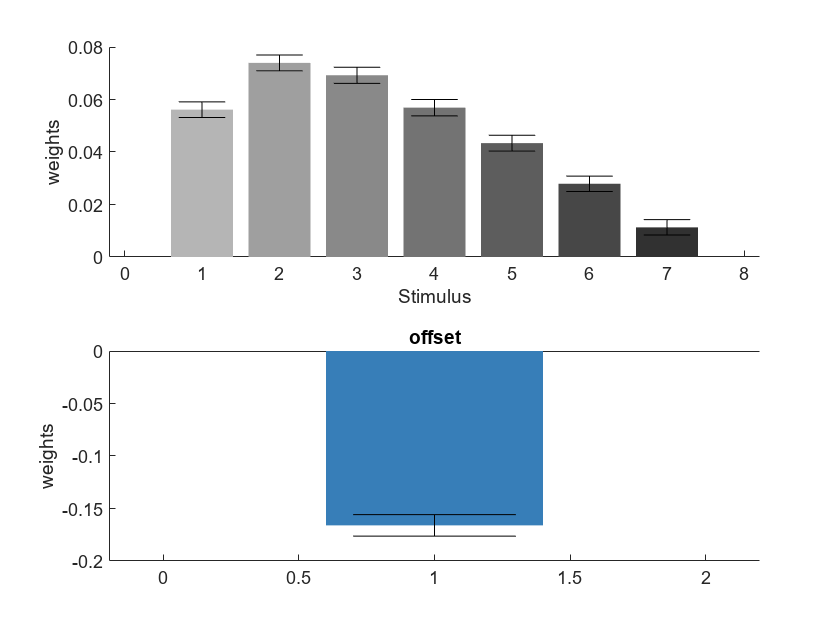

figure;
M.plot_weights;

#### Model validation

We can then perform *model validation* (also known as *posterior predictive checks*) using `plot_data_vs_predictor` to check whether the model captures well the statistical dependencies between the stimulus and choice. We observe that although the data does follow the sigmoidal curve as expected, there are some systematic deviations. A hint that some other factor(s) may also condition behavior.

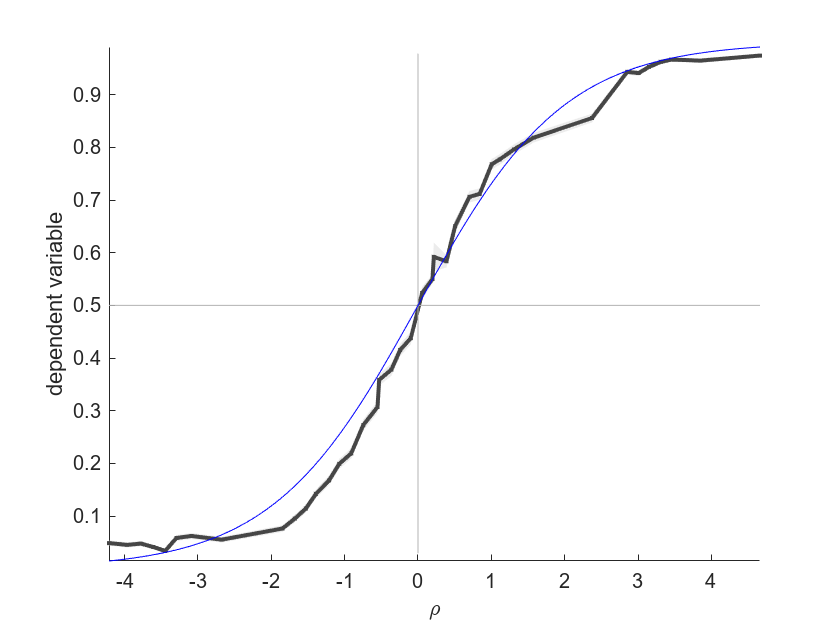

figure;
nQuantiles = 40; % we'll use 40 quantiles to compute the experimental psychometric cruve
M.plot_data_vs_predictor(nQuantiles);

For convenience we will rewrite this model using the variable '`Stimulus`' which stores the value of all seven motion pulses in each trial. This model is strictly equivalent to the previous one:

M = gum(T,'resp ~ Stimulus', 'prior','none');

#### Splitted regressors

We often want to know how the impact of a certain variable $x$ depends on the value of a certain categorical value $c$. This is easily done by declaring the regressor `x|c` in the formula. This basically splits regressors $x$ and creates a different set of regressors (with associated weights) for each level of the categorical variable. For example here we want to see how the impact of the stimulus varies across sessions so we declare the regressor `Stimulus|session`. (We illustrate it on the dataset restricted to the last 6 sessions for simplicity).

M = gum(T(T.session>106,:),'resp ~ Stimulus|session','prior','none');

By plotting the *design matrix* of the model we actually see that each set of 7 regressors is non-zero only for a continuous subset of trials corresponding to one session.

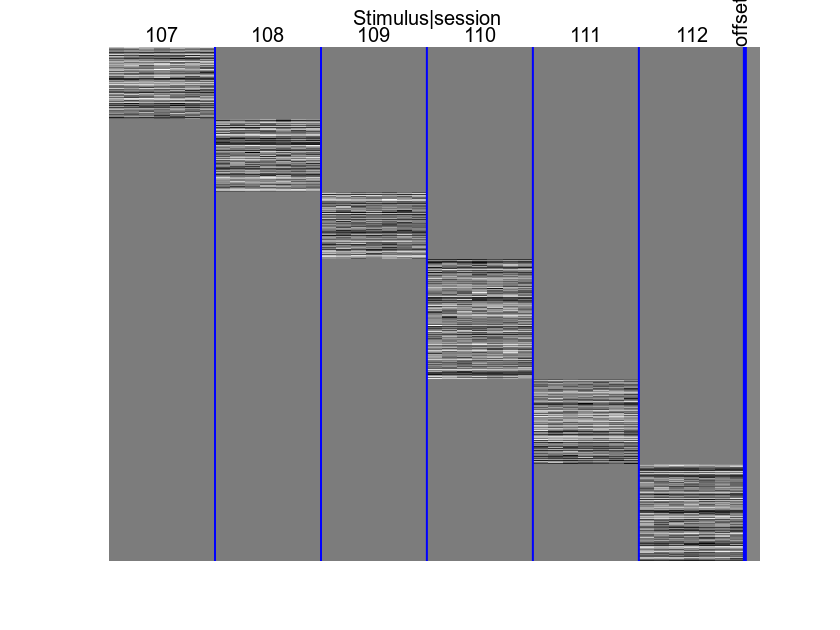

figure;
M.plot_design_matrix;

Let's infer the weights of this model and plot them: we see a different set of weights (a different colour) corresponding to each session.

figure;
M = M.infer;

Evaluating prior covariance matrix...done
****x*
converged after 6 iterations, log-joint:-1243.585246
Computing posterior covariance...done


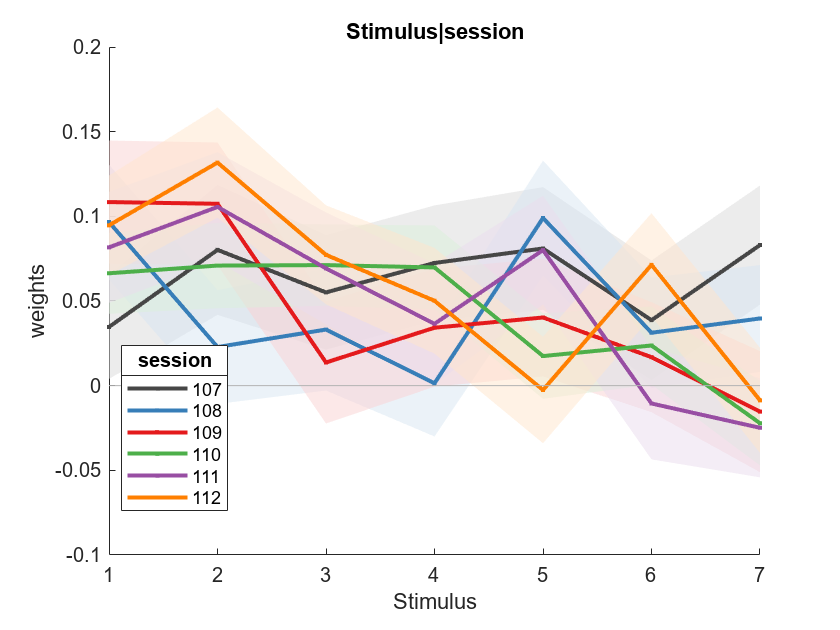

M.plot_weights("Stimulus|session"); % plot only weights for stimulus

#### Lagged regressors

Lagged regressors are used to capture the impact of regressors across time (across observations when they represent a sequential process; here across trials). Lagged regressors can be introduced by using the *lag() *operator in the GUM formula. For example the following model includes a regressor capturing the impact of the response on the previous trial, on trial *t-2 * and *t-3 * (i.e. lags=1,2, and 3). [Variable `response` is the response of the subject coded as -1/+1 for left/right].

M = gum(T,'resp ~ Stimulus + lag(response; lags=1:3)','prior','none');

Splitted regressors are simply regressors which are splitted based on the value of a categorical variable. Here we the impact of a recent response on the current choice will depend on whether that response was rewarded (i.e. correct) or not, so we split this regressor based on the value of `accuracy`*.*

M = gum(T,'resp ~ Stimulus + lag(response|accuracy; lags=1:3)','prior','none');

In the design matrix below, you can see that there are three regressors for correct responses, each lagged by one trial with respect to the previous one (and same for error responses).

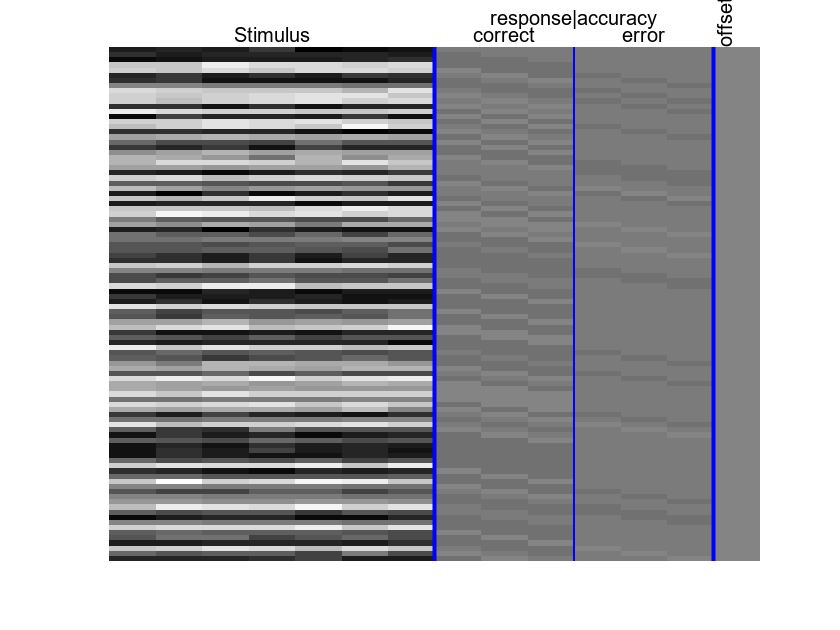

figure; 
M.plot_design_matrix(1:100); % plot design matrix for first 100 trials

Another interesting plot we can run prior to estimating the model is the plot of the *Variance Inflation Factor* (VIF). The VIF is a measure for each regressor of how much its estimation can be corrupted by the correlation to other regressors. Values close to one (the minimal) means very little corruption (as can be seen for lagged regressor here). Large values (especially larger than 10) indicate probablematic design with likely very large estimation noise. Here we see the VIF for stimulus weights are quite large (around 5) as they are quite correlated between themselves, which is why their weights in single sessions above are subject to large estimation noise. When estimating over the entire dataset, this is mitigated by the high statistical power offered by the large number of trials.

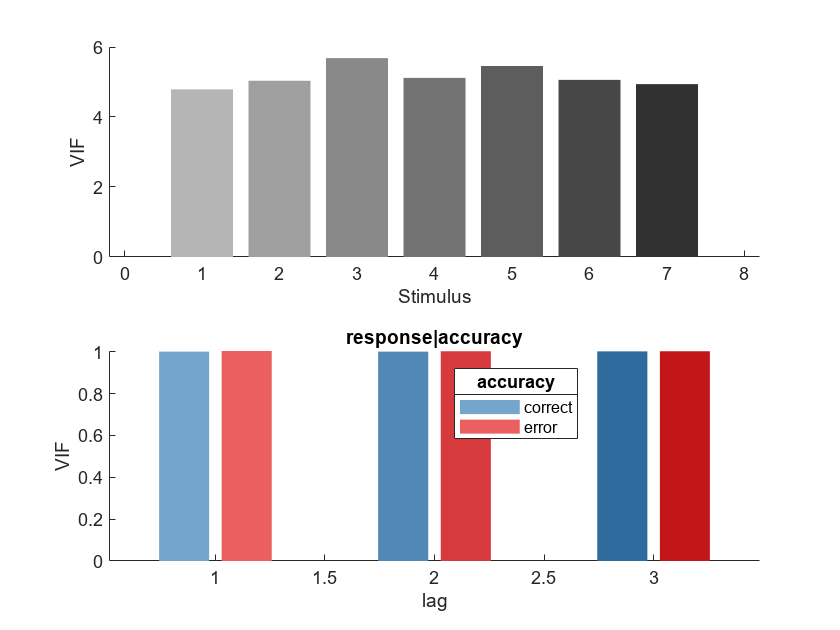

figure;
M.plot_vif;

We now estimate and plot the model weights as seen previously. We see that previous choices do have an impact on the current choice: counter-intuitively, this animal is biased towards repeating a response (positive weights) if that response was associated with an error in any of the previous 3 trials, and against repeating (negative weights) if it was rewarded!

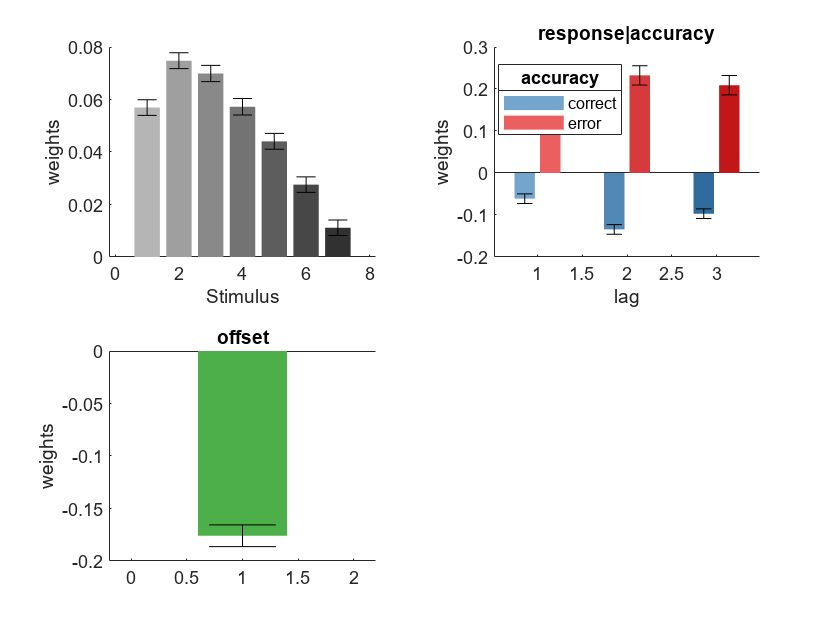

Evaluating prior covariance matrix...done
****x*
converged after 6 iterations, log-joint:-29410.898064
Computing posterior covariance...done


figure;
M = M.infer.plot_weights();

As a final note on GLMs: the default options is to include Gaussian priors on GLM weights. To understand how they work, how to set them or remove them, go to the full tutorial on GLMs.

#### Model comparison

The toolbox

Mstim = gum(T,'resp ~ Stimulus', 'label','stimulus','prior','none'); % model with only stimulus regressors
Mhist1 = gum(T,'resp ~ Stimulus + lag(response; lags=1:3)', ...
    'label','history simple','prior','none'); % model with lagged response regressors
Mhist2 = gum(T,'resp ~ Stimulus + lag(response|accuracy; lags=1:3)',...
    'label','full history','prior','none'); % model with lagged response/accuracy regressors

% concatenate into a 3-element array of models
M = [Mstim Mhist1 Mhist2];

% infer all model at once (note: we could also infer each separately and
% then concatenate)
M = M.infer();

Inferring weights for model 1/3:  stimulus ()
Evaluating prior covariance matrix...done
****x*
converged after 6 iterations, log-joint:-29669.877307
Computing posterior covariance...done

Inferring weights for model 2/3:  history simple ()
Evaluating prior covariance matrix...done
****x*
converged after 6 iterations, log-joint:-29647.954283
Computing posterior covariance...done

Inferring weights for model 3/3:  full history ()
Evaluating prior covariance matrix...done
****x*
converged after 6 iterations, log-joint:-29410.898064
Computing posterior covariance...done



% plot AIC and BIC for all models
figure;
M.plot_score({'AIC','BIC'});

Raw values of (penalized) likelihoods are not (or little) meaningful, relative values are. Which is why we can use one model as reference (here, the stimulus-only model) as compute the difference in AIC/BIC with respect to this model. Negative values indicate that other models outperform this one.

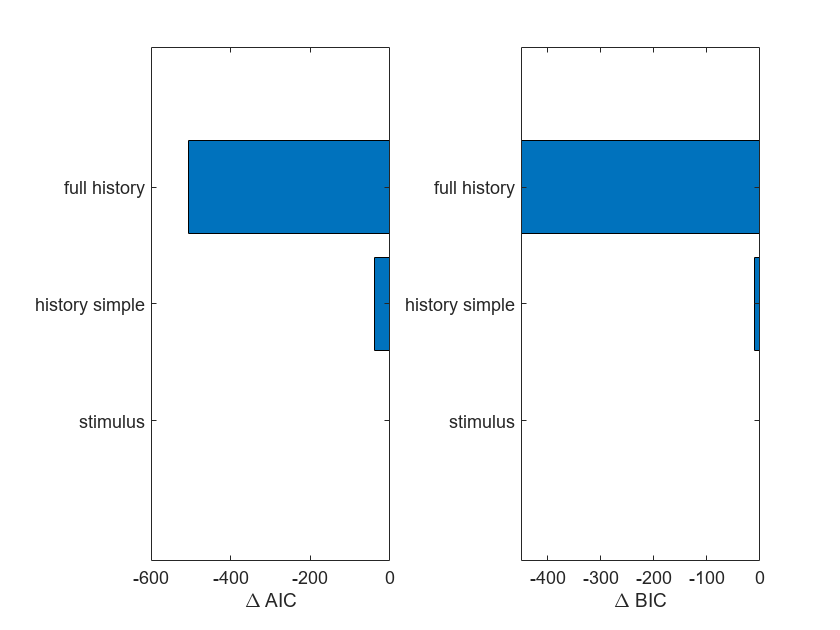

% plot AIC and BIC for all models
figure;
M.plot_score({'AIC','BIC'},'bar','stimulus');

### Capturing nonlinear mapping of regressors (*Generalized Additive Models*)

In many situations we don't expect a regressor to have a purely linear impact. For example, in a given session, we may expect that the lateral bias (the tendency of the animal to respond more towards one side or the other) will fluctuate over time. The toolbox allow to include the nonlinear impact of a regressor $x$ by declaring a nonlinear function $x$ in the formula. This is known as a *Generalized Additive Model* (GAM). Here we include a function  `f(trial) `which represents a nonlinear mapping of the trial index (`trial` is an integer representing the index of the trial within the session). The model is run over a single session (session 100): 

Tsingle = T(T.session==100,:); % dataset for single session (session 100)
M = gum(Tsingle,'resp ~ Stimulus + f(trial)');

The smoothness of the function (i.e. how fast it can change from session to session) depends on the prior which is set using Gaussian Processes (specifically a Squared Exponential prior). More concretely, there are two hyperparameters that control the variance and time scale of this prior. The value of weight estimates will depend on the value of these hyperparameters. Here we use the command `fit()` instead of `infer()` which allows to jointly estimate the weights (or rather the posterior distribution over the weights) and the hyperparameters. (Fitting this model can take a few minutes so please be patient or go get a coffee)

M = M.fit();

Initial weight inference (10 starting points):*
HP fitting: iter 1, log evidence -251.864319
HP fitting: iter 2, log evidence -236.840199
HP fitting: iter 3, log evidence -236.708515
HP fitting: iter 4, log evidence -236.704149
HP fitting: iter 5, log evidence -236.701735
HP fitting: iter 6, log evidence -236.688193
HP fitting: iter 7, log evidence -236.686169
HP fitting: iter 8, log evidence -236.678296
HP fitting: iter 9, log evidence -236.673384
HP fitting: iter 10, log evidence -236.669982
HP fitting: iter 11, log evidence -236.667636
HP fitting: iter 12, log evidence -236.666000
HP fitting: iter 13, log evidence -236.664649
HP fitting: iter 14, log evidence -236.663436
HP fitting: iter 15, log evidence -236.662384
HP fitting: iter 16, log evidence -236.661527


Now we can just plot the weights, as previously. We indeed some fluctuations in the lateral bias across trials (the blue curve), as the animal displays a larger bias towards the rightward response around trials 400-500.

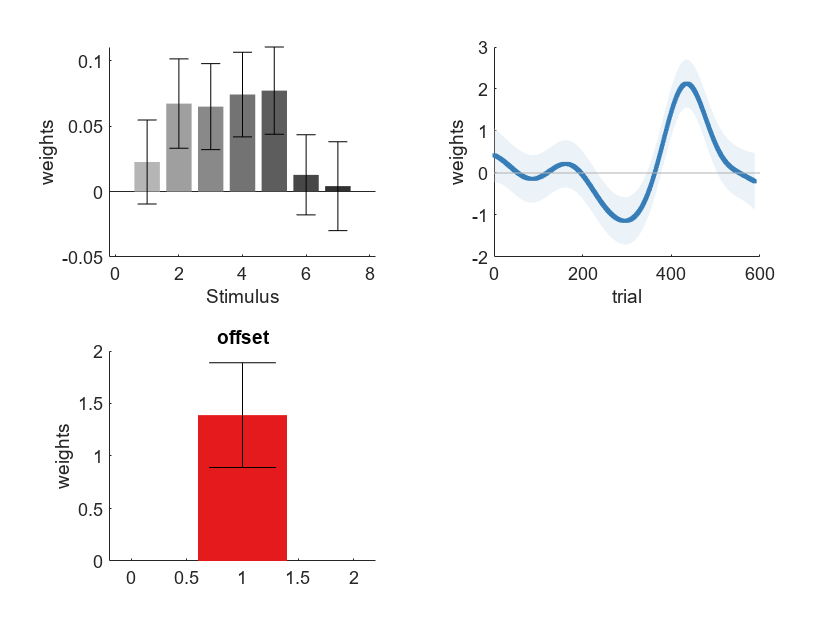

figure;
h = M.plot_weights;

We can also plot the hyperparameters of the model. In particular, $\tau$, the scale hyperparameter, reflects the time scale at which the bias fluctuates (here approximately 55 trials).

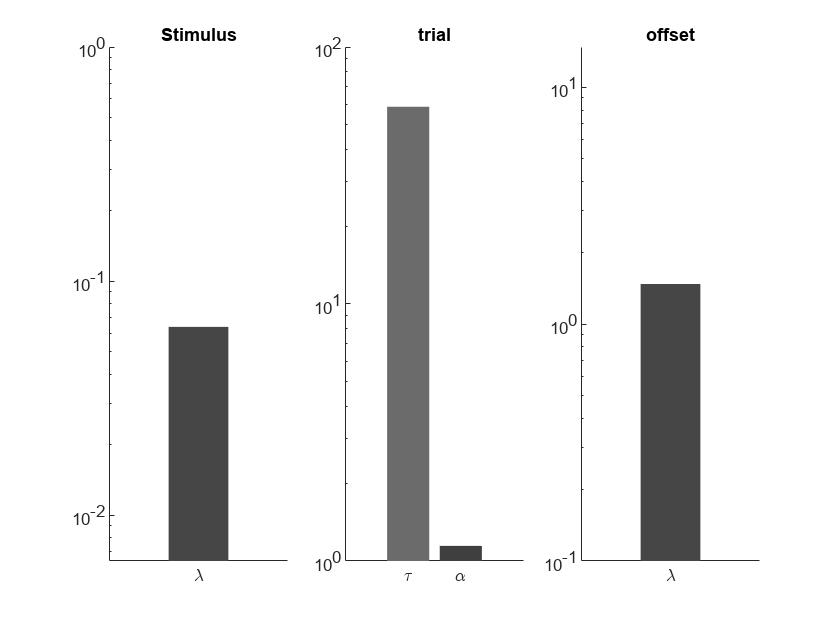

figure; 
M.plot_hyperparameters;

#### Basis functions

Another possibility for capturing the nonlinear mapping of regressors is to used a set of **basis functions**. For example we could capture the session-wise bias using a 5th order polynomial using the formula.

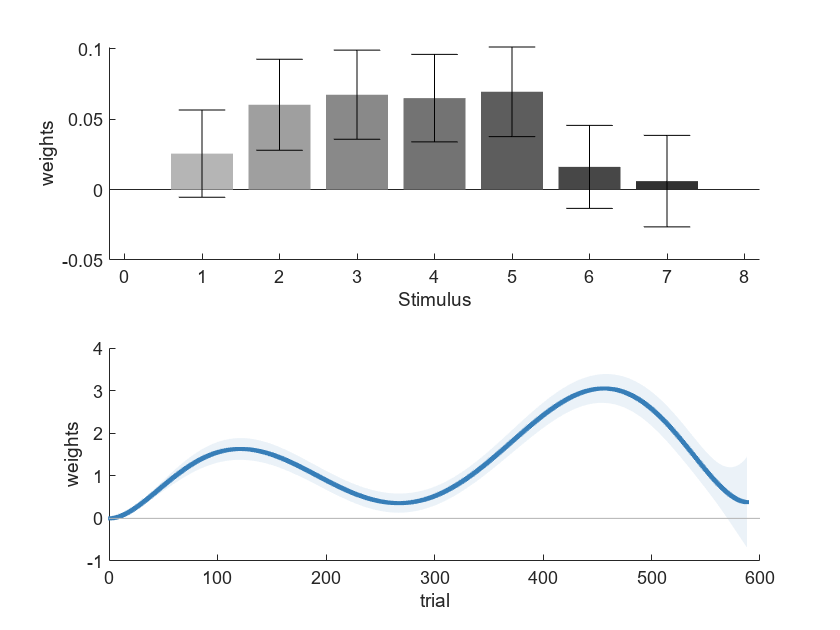

Initial weight inference (10 starting points):*
HP fitting: iter 1, log evidence -370.155396
HP fitting: iter 2, log evidence -329.660947
HP fitting: iter 3, log evidence -324.886363
HP fitting: iter 4, log evidence -320.502112
HP fitting: iter 5, log evidence -316.546609
HP fitting: iter 6, log evidence -314.050483
HP fitting: iter 7, log evidence -313.350489
HP fitting: iter 8, log evidence -313.254652
HP fitting: iter 9, log evidence -313.247664
HP fitting: iter 10, log evidence -313.249586
HP fitting: iter 11, log evidence -313.251107
HP fitting: iter 12, log evidence -313.251842


M = gum(Tsingle,'resp ~ Stimulus + poly6(trial)');
figure;
M.fit.plot_weights;

Using basis functions may feel more intuitive than the default option when declaring `f(x)`, which relies on Gaussian Processes. However Gaussian Processes are more powerful as they do not require you to define *a priori *a set of basis functions over which the function to be inferred can be decomposed (actually Gaussian Processes rely on an *infinite number* of basis functions, technically speaking). 

#### Basis functions for lagged regressors

Basis functions can also be used for lagged regressors. Because the number of regressors scales with the number of lags, statistical power can prevent from including many lags into the model. This can be circumvented by assuming that the lags map onto a few exponential basis functions, i.e. weight at lag *l *follows $w_L = \sum_{k \leq 2} \exp(-l/ \tau_k)$. Here $\tau_k$ are hyperparmeters of the model which can be estimated using the `fit()` command.

M = gum(Tsingle,'resp ~ Stimulus + lag(resp|accuracy; lags=1:20; basis=exp2)').fit();

Initial weight inference (10 starting points):*
HP fitting: iter 1, log evidence -257.307190
HP fitting: iter 2, log evidence -241.990789
HP fitting: iter 3, log evidence -241.794363
HP fitting: iter 4, log evidence -241.783535
HP fitting: iter 5, log evidence -241.784377


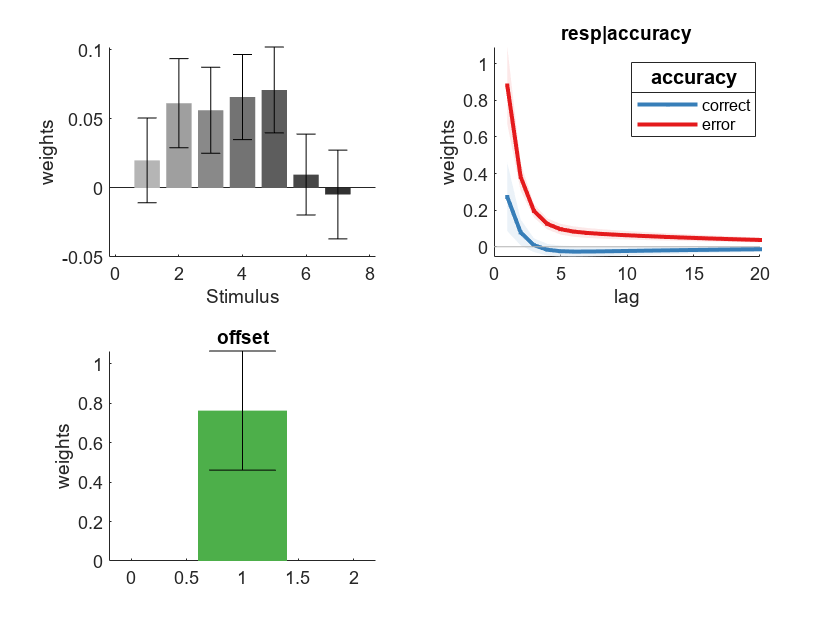

figure;
M.plot_weights;

Of course the two types of nonlinear mapping can be combined in a single formula, e.g. we could estimate the session-wise bias and history-dependent biases jointly using the following model:

M = gum(Tsingle,'resp ~ Stimulus + f(trial) + lag(resp|accuracy; lags=1:20; basis=exp2)');

Learn more about how to capture nonlinear mappings of regressor in our [dedicated tutorial](matlab:open('./nonlinear_mapping.mlx')): the different types of basis functions, how to adjust their hyperparameters, capture mappings of more than one variable, and more.

### Modelling over population

Often we want to run the same regression model in different datasets: different subjects of an experiment, different neurons whose activity we recorded, and so on. Here we showcase how to use GUM for regression over a population (i.e. a collection of datasets). We will use the different experimental sessions as different datasets and run regression models on individual sessions. (We will restrict to the first 6 sessions for simplicity).

We can build simply separate models for different datasets split by a categorical variable $c$ simply by declaring `y|c `on the left hand side of the formula (before the `~ `sign). So here '`resp|session ~ ...'` indicates that we build a different model of responses for each session.

T_first = T(T.session<=6,:); % dataset of first 6 sessions
M = gum(T_first,'resp|session ~ Stimulus + lag(resp|accuracy; lags=1:3)',...
    'label','full'); % build one model for each session in dataset

Actually this generates a different GUM object for each session, so now `M` is an array of 6 models:

fprintf("created " + length(M) + " models");

created 6 models

We fit all models in a single code line:

M = M.fit('verbose','little');

fitting model 1/6:  full (session=1)...
******************************************************done!
Final evidence (54 iterations): -130.642169

fitting model 2/6:  full (session=2)...
************************done!
Final evidence (24 iterations): -613.407285

fitting model 3/6:  full (session=3)...
************************done!
Final evidence (24 iterations): -453.497887

fitting model 4/6:  full (session=4)...
*************************done!
Final evidence (25 iterations): -586.107588

fitting model 5/6:  full (session=5)...
**********done!
Final evidence (10 iterations): -587.112842

fitting model 6/6:  full (session=6)...
***********************************************************done!
Final evidence (59 iterations): -102.490578



As we can see `M(1)` correspond to the model fitted to the data in session 1:

disp(M(1));

Generalized Unrestricted Model (GUM) object:  full (session=1)
resp|session ~ Stimulus + lag(resp|accuracy; lags=1:3)
--------------------------------------------------------------------------------
            Type:            GLM         Observations:       binomial
 nRegressorBlock:            310     ObservationBlock:              3
   nObservations:            310          isEstimated:              1
        isFitted:              1              Dataset:       1.000000
     nParameters:             14      nFreeParameters:             14
              df:            296     nFreeHyperparameters:              3
         scaling:       1.000000     SplittingVariable:            NaN
   LogLikelihood:    -123.938297             LogPrior:      -1.995780
        LogJoint:    -125.934077             exitflag:              1
     LogEvidence:    -130.642169            BIC_infer:     328.188607
       AIC_infe

We can **plot all models jointly** by first concatenating them into a single model object using the method `concatenate_over_models`. Then we can plot it as we have seen before, and see a different line for each session on each panel.

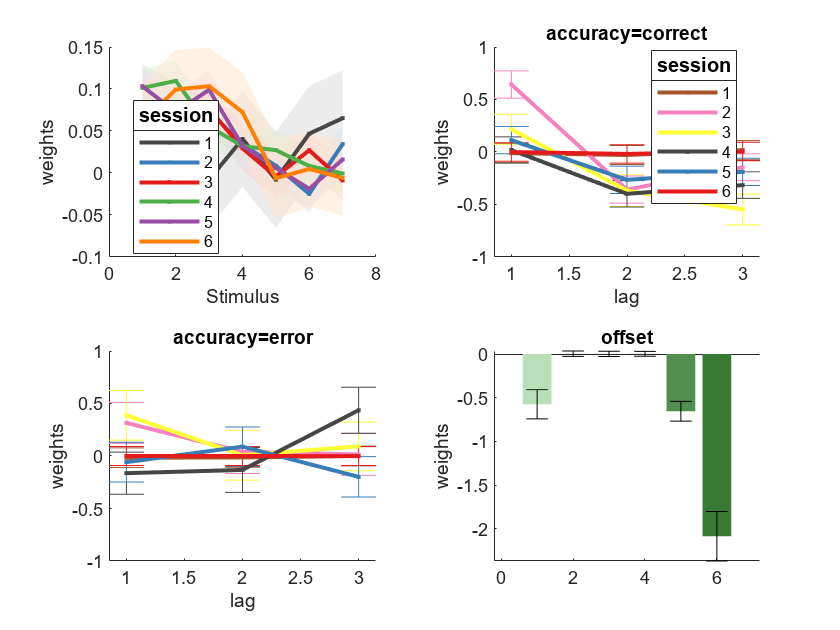

Mconc = M.concatenate_over_models; % concatenating all 6 models into a single model object
figure;
Mconc.plot_weights(); % plotting weights jointly

It is also possible to **average weights** over the population by using `population_average`. We can then plot the average weights using `plot_weights` (the error bars now correspond to the standard error of the mean).

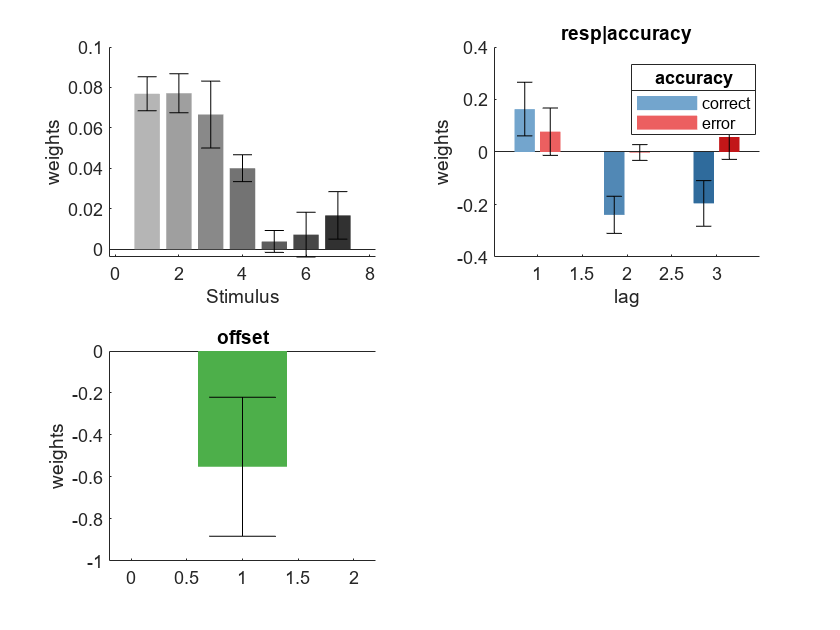

Mavg = M.population_average; % averaging weights across 6 sessions
figure; 
Mavg.plot_weights; % plotting average weights

Finally we can perform model comparison between different models across datasets. Let us first create another model with stimulus-only regressors, fit separately on the same 6 sessions.

Mstim = gum(T(T.session<=6,:),'resp|session ~ Stimulus','label','stimulus only');
Mstim = Mstim.fit('verbose','little');

fitting model 1/6:  stimulus only (session=1)...
**********done!
Final evidence (10 iterations): -130.589007

fitting model 2/6:  stimulus only (session=2)...
*******done!
Final evidence (7 iterations): -622.943570

fitting model 3/6:  stimulus only (session=3)...
*****done!
Final evidence (5 iterations): -462.191538

fitting model 4/6:  stimulus only (session=4)...
****done!
Final evidence (4 iterations): -593.449200

fitting model 5/6:  stimulus only (session=5)...
****done!
Final evidence (4 iterations): -588.945807

fitting model 6/6:  stimulus only (session=6)...
*******done!
Final evidence (7 iterations): -102.435890



Now let us concatenate these two models into a single model array (of 6x2=12 elements) and use `plot_score` to plot the Akaike Information Criterion (AIC). We use the 'stimulus-only' model as reference. Negative values for the full model shows that this model is favoured over the stimulus-only model (in 4 out of 6 sessions). 

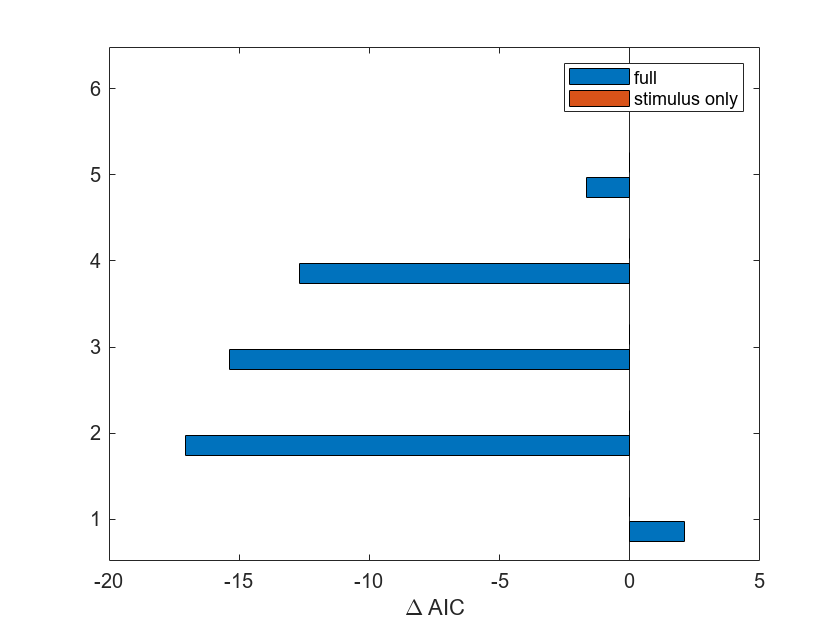

Mboth = [M Mstim];
figure;
Mboth.plot_score('AIC','bar','stimulus only');

#### **Products of regressors**

One unique feature of the GUM toolbox is the ability to include product of regressors in the predictor formula such as `f(x)*f(y)`. This allows to capture a richer set of regression problems than the typical Generalized Linear Models or Generalized Additive Models. This is helpful in general when we want to **test whether one variable modulates the impact of another. ** We illustrate here with a model with two sets of regressor products:

-  the first set will capture the impact of the stimulus sequence modulated within session. This is written in the formula as `Stimulus*f(trial)`: `Stimulus` captures the linear effect of the stimulus sequence (`Stimulus` is a 7-element array, so the model will estimate a 7-element vector of weights), while `f(trial)` captures the nonlinear impact of time in session (trial index).

- the second set will capture the impact on current response of recent history (history of last 6 responses), modulated across session. This is in written in the formula by  `lag(response;lags=1:5)*f(session)`, where the term before the multiplicative sign encodes for the history effect and the term after the multiplicative sign encodes for the impact of session.

M = gum(T,'resp ~ Stimulus*f(trial) + lag(response|accuracy;lags=1:5)*f(session)');
M = M.fit('maxiter',30); % fit model (with max 30 iterations of the EM algorithm to speed up results)

Initial weight inference (10 starting points):****x****o
HP fitting: iter 1, log evidence -29308.919371
HP fitting: iter 2, log evidence -29272.198168
HP fitting: iter 3, log evidence -29268.490575
HP fitting: iter 4, log evidence -29265.156129
HP fitting: iter 5, log evidence -29264.531514
HP fitting: iter 6, log evidence -29264.120168
HP fitting: iter 7, log evidence -29263.708302
HP fitting: iter 8, log evidence -29263.486572
HP fitting: iter 9, log evidence -29263.467431
HP fitting: iter 10, log evidence -29263.458799
HP fitting: iter 11, log evidence -29263.453570
HP fitting: iter 12, log evidence -29263.450871
HP fitting: iter 13, log evidence -29263.449170
HP fitting: iter 14, log evidence -29263.448157
HP fitting: iter 15, log evidence -29263.447429


We see here how time in session modulates stimulus processing: the stimulus weights is low in the very first trials of each session (i.e. the animal performs badly), then rises sharply, plateaus and starts falling down as the animal likely loses motivation and focus.

We also see that history effects gradually decay across sessions (with some importat fluctuations on top of this general decay).

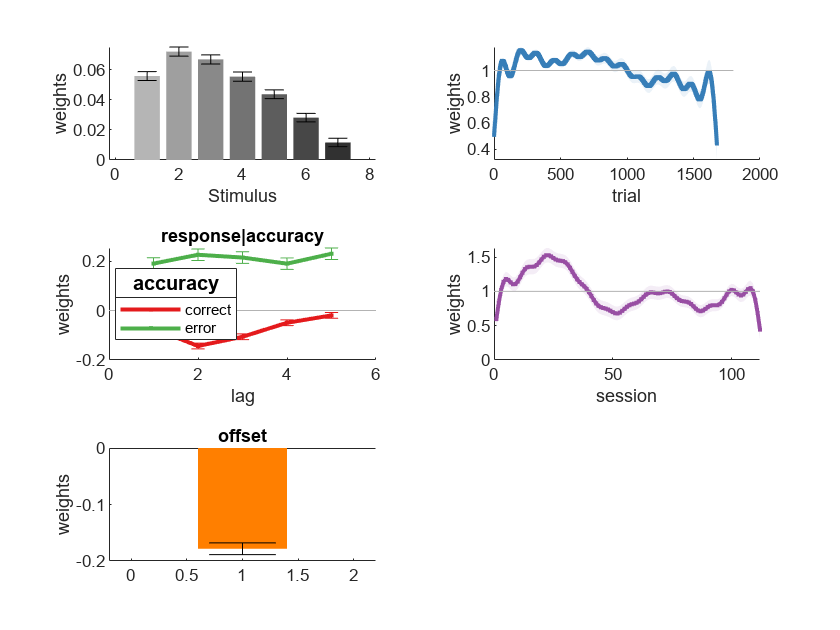

figure;
M.plot_weights;

#### **Explore in depth:**

We cover the functionalities of the toolbox more in depth in our full collection of tutorials:

- [Building a model](matlab:open('./building_a_model.mlx'))

- [Nonlinear mapping of input variables](matlab:open('./nonlinear_mapping.mlx'))

- COMPLETE!